% python reference
% https://github.com/zacstewart/apt-decoder/blob/master/apt.py


% Test 
clc;clear;close all;



% read in file
[sig,Fs,success] = read_wav();

Selected file: /home/seth/Documents/Classes/EE6220/project/noaa-toolkit/software/src/test_11025hz.wav



% graph if able to open file
if success
    [apt_image,raw_vals,offsets] = noaa_decode(sig,Fs);
else
    disp("Error opening File")
end



% graph
test = 4

test = 4

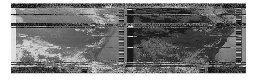

figure;
imshow(apt_image, []);

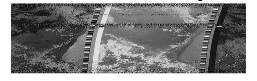

imshow(raw_vals, []);

colormap gray;
axis equal;
title('NOAA APT Decoded Image');


imwrite(apt_image, 'grayscale_image.png'); % Save as PNG
